# Zatman算法

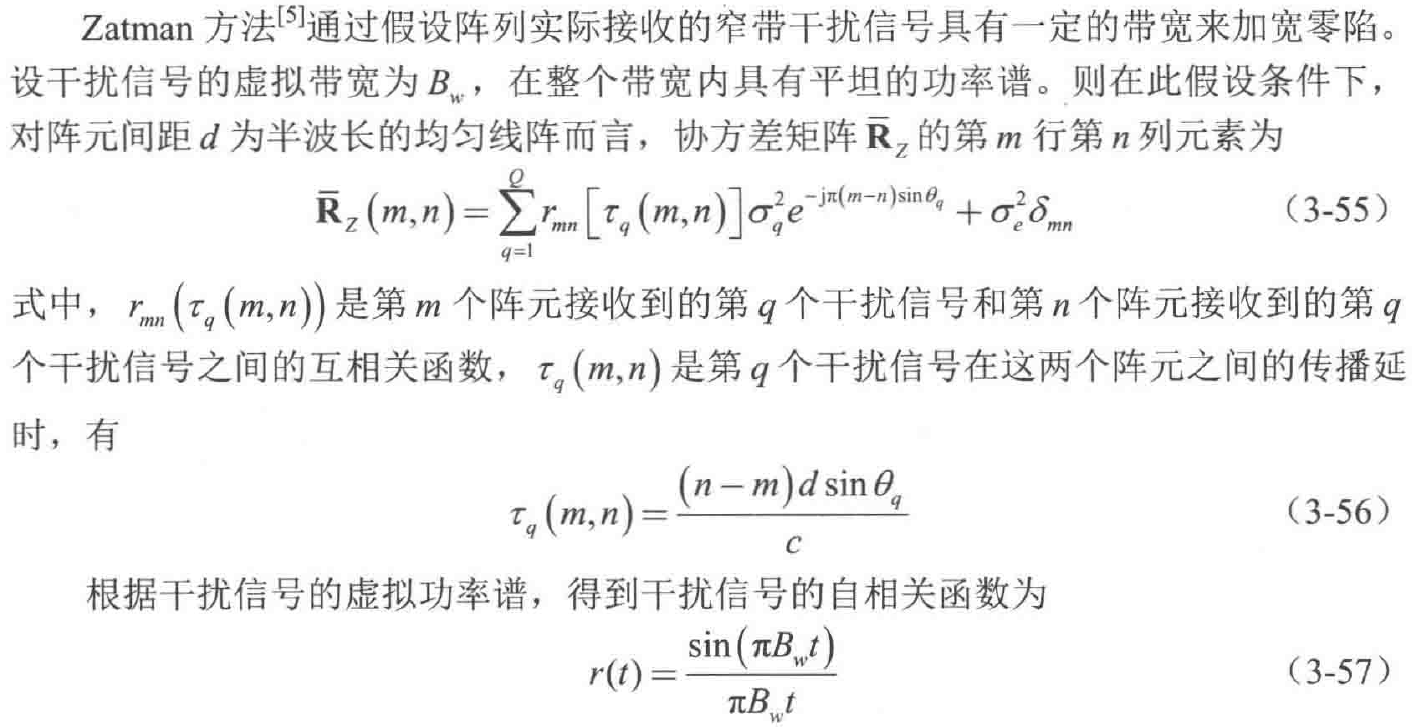

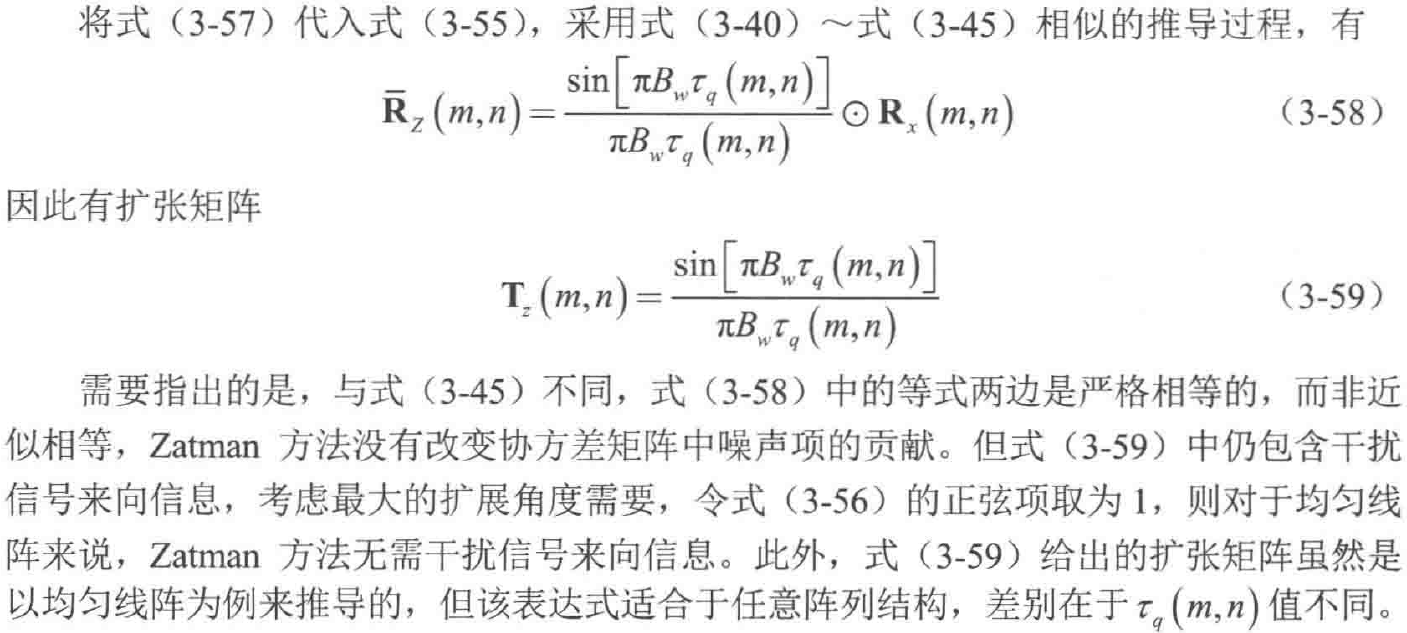

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 8;                                                                      %阵元个数
%--------------------------------------------------------------------------
theta_tgt = [-10];                                                             %信号来向
%--------------------------------------------------------------------------
theta_jam = [20];                                                        %干扰来向
theta = [theta_tgt theta_jam];
%--------------------------------------------------------------------------
M = numel(theta);                                                           %信源个数
snr = 10;                                                                   %信噪比
K = 1024;                                                                   %采样点数

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形

%--------------------------------------------------------------------------
%   接收信号为随机值
%   并按照阵列流形构造回波相位                                  
%--------------------------------------------------------------------------
S = randn(M,K) + 1j.*randn(M,K);                                            %构建接收信号
S(1,:) = S(1,:).*1;                                                       %信号功率小，干扰功率大,如果信号功率大了 也会默认为干扰位置
X = A*S;                                                                    %对信号来向进行仿真
X1 = awgn(X,snr,'measured');

%--------------------------------------------------------------------------
%   构造接收信号的协方差矩阵
%--------------------------------------------------------------------------
Rx = X1*X1';

T = T_zatman(0.005,N,N)                                                     %扩张协方差矩阵

T =     1.0000    0.9969    0.9875    0.9721    0.9506    0.9235    0.8910    0.8535
    0.9969    1.0000    0.9969    0.9875    0.9721    0.9506    0.9235    0.8910
    0.9875    0.9969    1.0000    0.9969    0.9875    0.9721    0.9506    0.9235
    0.9721    0.9875    0.9969    1.0000    0.9969    0.9875    0.9721    0.9506
    0.9506    0.9721    0.9875    0.9969    1.0000    0.9969    0.9875    0.9721
    0.9235    0.9506    0.9721    0.9875    0.9969    1.0000    0.9969    0.9875
    0.8910    0.9235    0.9506    0.9721    0.9875    0.9969    1.0000    0.9969
    0.8535    0.8910    0.9235    0.9506    0.9721    0.9875    0.9969    1.0000


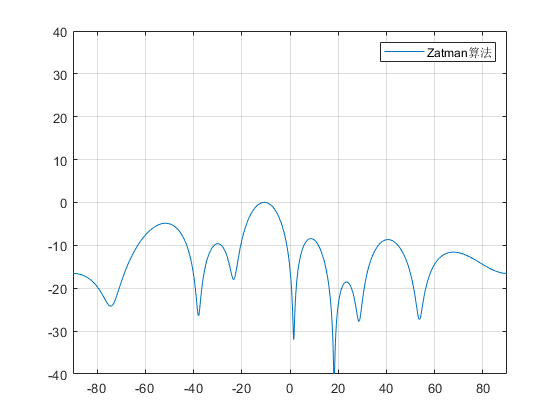


Rx_tilde = T.*Rx;
%--------------------------------------------------------------------------
%   构造delta_m 约束最小功率
%--------------------------------------------------------------------------
delta_m = zeros(N,1);
delta_m(1) = 1;

%--------------------------------------------------------------------------
%   最优权矢量为
%--------------------------------------------------------------------------
% w     = (delta_m'*Rx_tilde^-1*delta_m)^-1*(Rx_tilde^-1*delta_m);            %原始结果
w     = Rx_tilde^-1*A(:,1)./(A(:,1)'*Rx_tilde^-1*A(:,1));                   %Zatman对MVDR进行调整
%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
idx = 1;
for theta_d = -90:0.1:90
    A1 = exp(1j.*2*pi*d.'*sind(theta_d));
    output1(idx) = w'*A1;
    idx = idx + 1;
end

%--------------------------------------------------------------------------
%   计算 信号 干扰角度
%--------------------------------------------------------------------------


figure(1)
plot(-90:0.1:90,db(abs(output1)));grid on;
axis([-90 90 -40 40])
legend('Zatman算法')


%--------------------------------------------------------------------------
%   Zatman算法扩张矩阵T(线阵)
%   theta_q         指向角度 degree
%   K               虚拟干扰源
%   m行
%   n列
%--------------------------------------------------------------------------

function T = T_zatman(theta_q,m,n)
dd = 0.5;                               %阵列间距
Bw = 100e1;                             %100Mhz
for mdx = 1:m
    for ndx = 1:n
        tao_q = (ndx-mdx)*dd*sind(theta_q);
        if mdx == ndx
            T(mdx,ndx) = 1;
        else
            T(mdx,ndx) = sin(pi*Bw*tao_q)/(pi*Bw*tao_q);
        end
        
    end
end
end